# Segment Images with Code

When segmenting images, there are often multiple good approaches. You'll usually need to experiment with different workflows. Changing your preprocessing steps will likely affect your segmentation steps and how much refinement you'll need. In this reading, you'll explore different approaches to segmenting the same image.

As part of your segmentation workflows, you may find yourself needing to incorporate the use of code. For example:

- your segmentation uses approaches such as color thresholding, edge detection, or multiple thresholds that are not done using the Image Segmenter App.

- you need to iterate on both preprocessing and morphology steps since, for example, filtering results may affect morphology.

In this reading you'll work with one of the crack images to: 

- Find multiple threshold levels to generated multi-label masks 

- Convert multi-label images into binary masks using logical operations 

- Generate structuring elements and perform morphological refinement 

- Incorporate preprocessing steps into a segmentation workflow 

- Compare multiple masks  

**Run the following script sections one at a time as you proceed. **

## Load and Examine an Image 

Use the code below to load and view one of the crack images. 

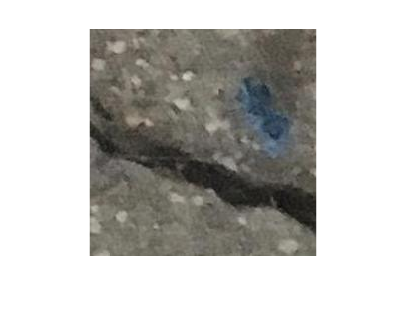

I0 = imread("00146.jpg");
imshow(I0); 

There is a large crack across the middle of this image. There appear to be some lighter colored rocks and debris on the surrounding concrete and a blue object in the upper right. Convert the image to grayscale and view the result. 

### Convert to Grayscale

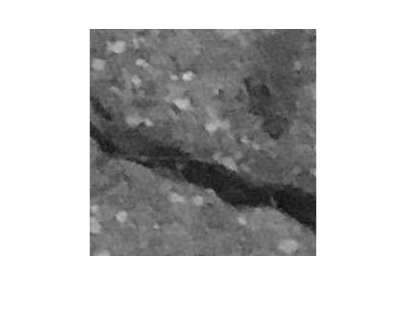

I = im2gray(I0);
imshow(I)

## **Create an Initial Mask**

The grayscale image appears to have three noticeable clusters of intensity: the very dark crack pixels, the moderately dark pixels mostly in the upper right area, and the brighter pixels making up the majority of the concrete and debris. Using multiple threshold levels will help more accurately isolate the crack from the other regions. To get three levels for dark, moderately dark, and brighter pixels, you need two thresholds. Use the `multithresh` function to do this. 

### Start with a Multi-label Mask

nThresh = 2;
threshValues = multithresh(I,nThresh)

threshValues = 1×2 uint8 row vector
    73   110


Once you have the threshold values from `multithresh`, you need to quantize the image using the `imquantize` function: 

L = imquantize(I,threshValues);

The label matrix `L` returned by `imquantize` is a matrix of data type double containing whole numbers from one to the number of levels. The `imshow` function expects images of type double to have a range of 0 to 1. To account for this, use empty square brackets as a second input argument. This makes the `imshow` function automatically scale the range of values in the input matrix for display. (You can also use the `rescale` function to directly rescale `L` to the expected range.) 

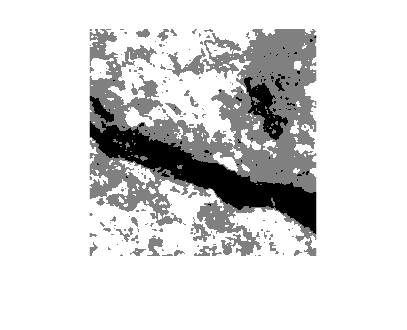

imshow(L,[])

### Convert to a Binary Mask

The result with three levels is pretty good. The crack is almost entirely black pixels (level 1), while most the remainder of the image is gray or white pixels (levels 2 and 3). To create a binary mask from this, use a logical operator to assign pixels in `L` equal to 1 as false, and pixels in `L` above 1 as true.   

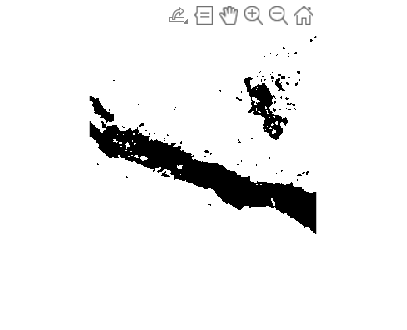

BW = L > 1;
imshow(BW)

## Refine the Mask 

Although the binary mask above is pretty good, it could still use some work. There are unwanted false pixels in the upper right and a few around the crack edges. There are also some extra true pixels crossing areas of the crack. 

### Use Morphology

Start with a small morphological *opening operation* to get rid of these extra true pixels. The first step for any morphological operation is to create a structuring element using the `strel` function. Use the `strel` function to create the structuring element for the `imopen, imclose, imdilate,` and `imerode` functions. 

se = strel("disk",4,0);

Here, we use a disk of radius 4. The first input is a string specifying the shape, in this case `"disk"`. The second input is the size of the shape. For a disk, the size parameter is the radius, in this case `4`. For a rectangular structuring element you need to specify the height and width of the rectangle as a vector, for example: `[3 6]`.  When using the disk shape, the third input specifies a level of approximation to the shape since a perfectly circular structuring element is not possible. Unless this is necessary, it is best to use `0` to specify no approximation. See the [documentation](https://www.mathworks.com/help/images/ref/strel.html) for more information. 

Once you have the structuring element, use it as a second input to the morphology function you need. In this case, use `imopen` to perform an opening operation. 

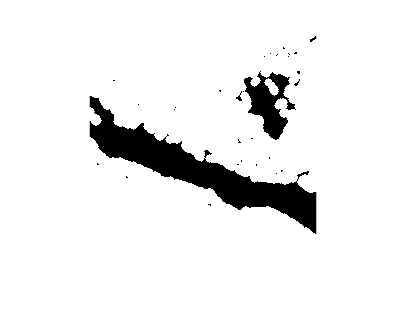

BW = imopen(BW,se);
imshow(BW)

The edges of the crack look like they could use a bit more refining. A morphological closing step should help (opening and closing are often used together). Here, we use the same structuring element for closing as for the open operation, but you can create a new structuring element with a different size or shape depending on your needs.

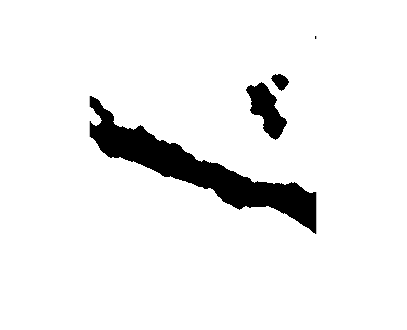

BW = imclose(BW,se);
imshow(BW)

### Fill Remaining Holes

This is not bad. However, the blue area in the upper right is mis-identified as crack. Both areas with false pixels in the upper right need to be corrected. The larger of the two is wider than sections of crack in this image, which means it is too large to close with morphology. For this reason, use the `imfill` function to perform a Fill Holes step. 

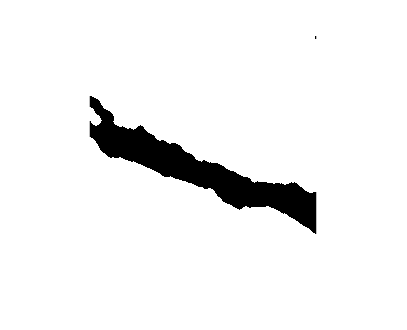

BW = imfill(BW,"holes");
imshow(BW)

### Invert the Mask

Since we are considering the crack itself to be foreground, invert the mask using `imcomplement`. (Since the mask is binary you could use the `~` operator on `BW` as well.) 

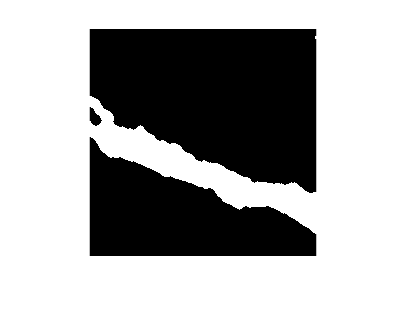

BW = imcomplement(BW);
imshow(BW);

This looks good! Finally, use the code below to visualize the mask overlayed on the image. 

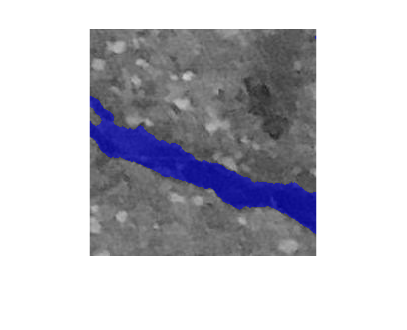

maskOn = labeloverlay(I,BW);
imshow(maskOn)

## Incorporate Filtering

Filtering and morphology are often linked. Look again at the multi-level thresholding below, the amount of debris and other noise in the image made the resulting segmentation jagged, and this required several steps to refine. 

imshow(L,[])

### Smooth the Grayscale Image

Filtering the image first can help with later processing steps. This is often the case with noisy images, or when the object of interest is large compared to smaller details. Here the main crack is much larger than the brighter debris, so filtering may help. We'll use 2-D Gaussian filtering with a standard deviation of 3. 

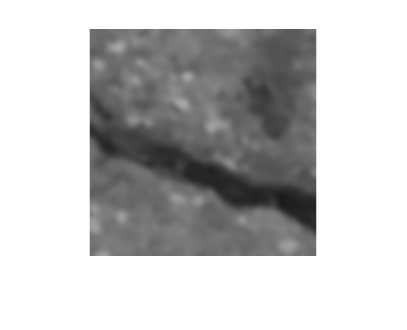

stdev = 3;
If = imgaussfilt(I,stdev);
imshow(If)

### **Create a Multi-label Mask**

The three clusters of intensity mentioned above are still present in the smoothed image. So, repeat the threshold steps above with two thresholds on the filtered image. 

threshValues = multithresh(If,nThresh)

threshValues = 1×2 uint8 row vector
    74   106


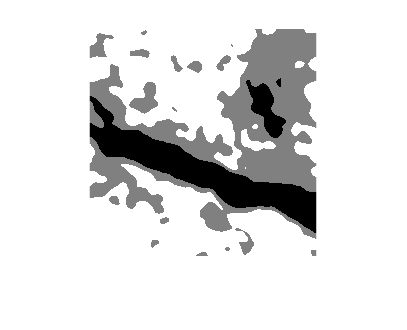

Lf = imquantize(If,threshValues);
imshow(Lf,[])

### Convert to a Binary Mask

Like before, the crack is almost entirely black pixels (level 1), but this time with much smoother edges due to the filtering. Again, most of the remaining image is gray or white (levels 2 and 3), but this time none are within the crack area. To create a binary mask from this, use a logical operator to assign pixels in `L` equal to 1 as false, and pixels in `L` above 1 as true.   

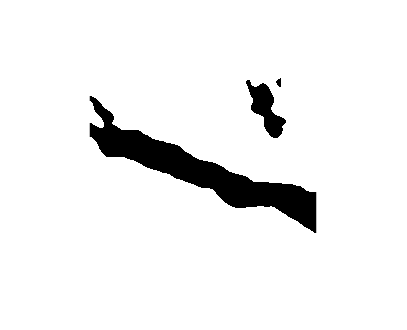

BWf = Lf > 1; 
imshow(BWf)

### Refine the Mask

This looks similar to the result achieved above, but without using morphology. The preprocessing step eliminated the need for morphology with this image. However, you still need to remove the large hole in the upper right. The same fill operation as before will work. 

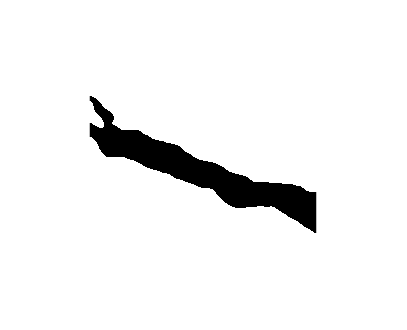

BWf = imfill(BWf,"holes");
imshow(BWf)

### Invert the Mask

Again, set the crack as foreground using the `imcomplement` function. 

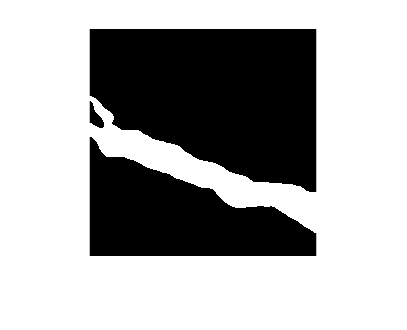

BWf = imcomplement(BWf);
imshow(BWf)

## Compare Final Masks 

Finally, compare the previous mask to this new one using `imshowpair. `The green and magenta regions show where the masks differ. See the [documentation](https://www.mathworks.com/help/images/ref/imshowpair.html) for other display options. 

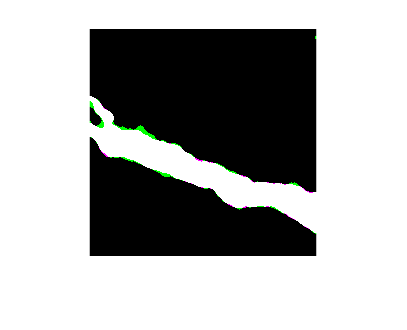

imshowpair(BW,BWf)

As you can see, the two masks are very similar, and both provide a good segmentation. There is usually no single correct answer when segmenting images, and no single correct workflow. Keep in mind that the preprocessing and enhancement steps you take will affect the results of thresholding as well as how much refinement is needed afterward. Don't be afraid to iterate back to an earlier stage in your workflow to try things out! 

*Copyright 2022 The MathWorks, Inc.*